Chain 3

N_states = 5;
N_chain = 500000;
Time = 100;
pi0 = ones(1,5)/5;

Find transition probabilities

X = chain_1(N_chain, Time, pi0);

P = zeros(N_states, N_states, Time);
number_of_transactions = zeros(N_states, N_states, Time);
total_visits = zeros(N_states, Time);

for t = 1:Time - 1
    for idx = 1:N_chain
        from = X(t, idx); to = X(t + 1, idx);
        number_of_transactions(from, to, t) = ... 
            number_of_transactions(from, to, t) + 1;
        total_visits(from, t) = total_visits(from, t) + 1;
    end
    for from = 1:N_states
        for to = 1:N_states
            P(from, to, t) = number_of_transactions(from, to, t) ...
                                / total_visits(from, t);
        end
    end
end 

figure
title('Transition probabilities chain 1')
xlabel('Time')
ylabel('Probability')   
hold on
grid on

for from = 1:N_states
    for to = 1:N_states
        values = zeros(int32(Time / 2 - 1), 1);
        for k = 1:int32(Time / 2 - 1)
            values(k) = P(from, to, 2 * k + 1);
        end
%         plot(1:Time-1, values, 'DisplayName', sprintf('%i->%i', i, j))
        plot( 1:int32(Time / 2 - 1), values);
    end
end

% legend('show')
hold off

c1)

N_chain = 10000000;
Time = 2;
N_try = 10;

P = zeros(N_states, N_states, N_try);

for i = 1:N_try
    X = chain_1(N_chain, Time, pi0);
    
    
    number_of_transactions = zeros(N_states, N_states, Time);
    total_visits = zeros(N_states, Time);
    
    for t = 1:Time - 1
        for idx = 1:N_chain
            from = X(t, idx); to = X(t + 1, idx);
            number_of_transactions(from, to, t) = ... 
                number_of_transactions(from, to, t) + 1;
            total_visits(from, t) = total_visits(from, t) + 1;
        end
        for from = 1:N_states
            for to = 1:N_states
                P(from, to, i) = number_of_transactions(from, to, t) ...
                                    / total_visits(from, t);
            end
        end
    end 
end

P_std_5 = std(P, 0, 3)

P_std_5 = 	1.0e+-3 *

    0.2047    0.1596    0.1146         0         0
    0.2939    0.2308    0.2236    0.3774         0
    0.2958    0.1030    0.2935    0.4775         0
         0    0.1492    0.1777         0    0.1834
         0         0         0    0.1617    0.1617


Chain 3 is not time homogenious!

e)

distributions = zeros(N_states, Time - 1);

for t = 1:Time - 1
    for idx = 1:N_chain
        state = X(t, idx);
        distributions(state, t) = distributions(state, t) + 1/N_chain;
    end
end

figure
title('Distribution on time for chain 1')
xlabel('Time')
ylabel('Probability')   
hold on
grid on

for state = 1:N_states
    plot( 1:Time - 1, distributions(state, :))
end
% legend('show')
hold off

f) Let's compute the error of a distribution

window_size = 10;
threshold = 0.001;
errors = zeros(Time - window_size, 1);
state_errors = zeros(N_states, Time - window_size);

for t = 1:Time - window_size - 1
    for state = 1:N_states
        state_errors(state, t) = std(distributions(state, t:t + window_size));
    end
    errors(t) = max(state_errors(:, t));
end


figure
title('Max std of dist on window od size 10')
xlabel('Time')
ylabel('STD')   
hold on
grid on
set(gca, 'YScale', 'log')


plot( 1 + window_size:Time, errors)
% legend('show')
hold off

limiting_distr = zeros(N_states, 1);
limiting_distr_slice = zeros(N_states, window_size);
for t = 1:Time - window_size - 1
    if errors(t) < threshold
        limiting_distr_slice = distributions(:, t:t + window_size);
        limiting_distr = mean(limiting_distr_slice, 2);
    end
end

figure
title('Limiting distribution')
xlabel('State')
ylabel('Probability')   
hold on
grid on
bar(limiting_distr)
hold off

g) 

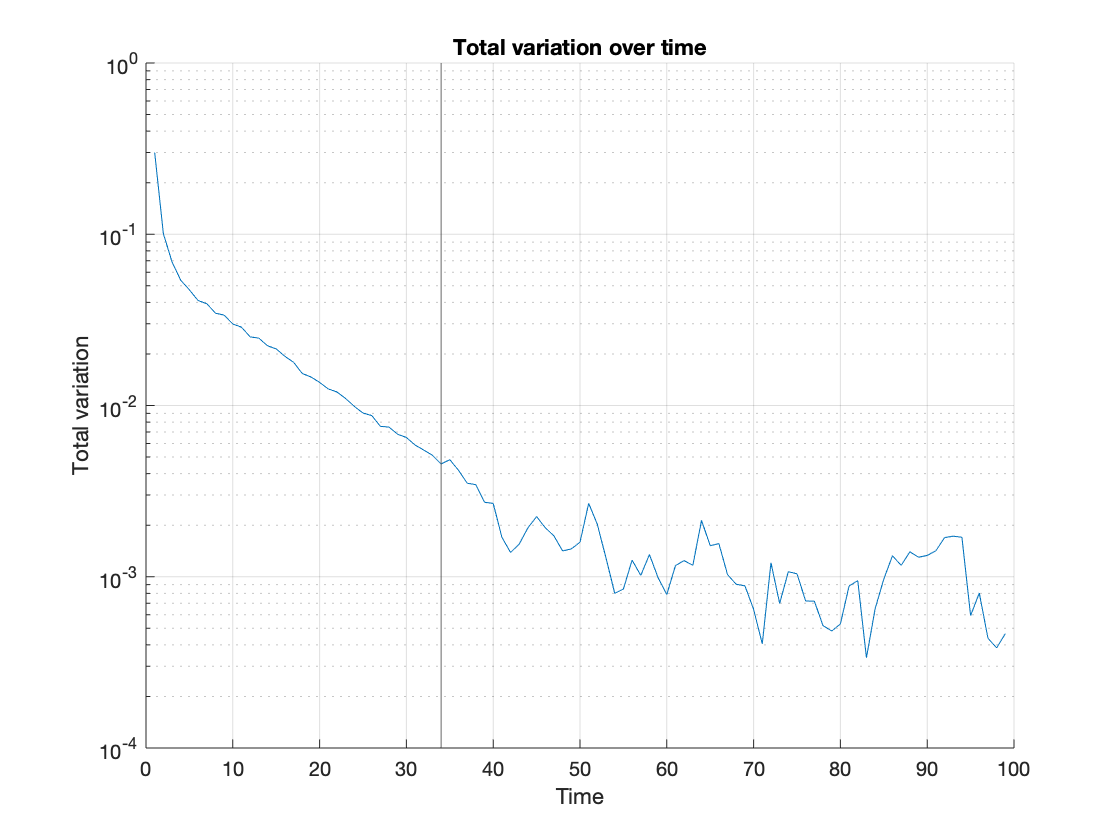

total_variation = zeros(Time, 1);
for t = 1:Time-1
    total_variation(t) = sum(abs(distributions(:, t) - limiting_distr)) / 2;
end

T_eps = 0;
eps = 0.005;
for t = 1:Time - 1
    if total_variation(t) < eps
        T_eps = t;
        break;
    end
end

figure
title('Total variation over time')
xlabel('Time')
ylabel('Total variation')   
hold on
grid on
set(gca, 'YScale', 'log')

plot( 1:Time, total_variation)
xline(T_eps);
% legend('show')
hold off

h)

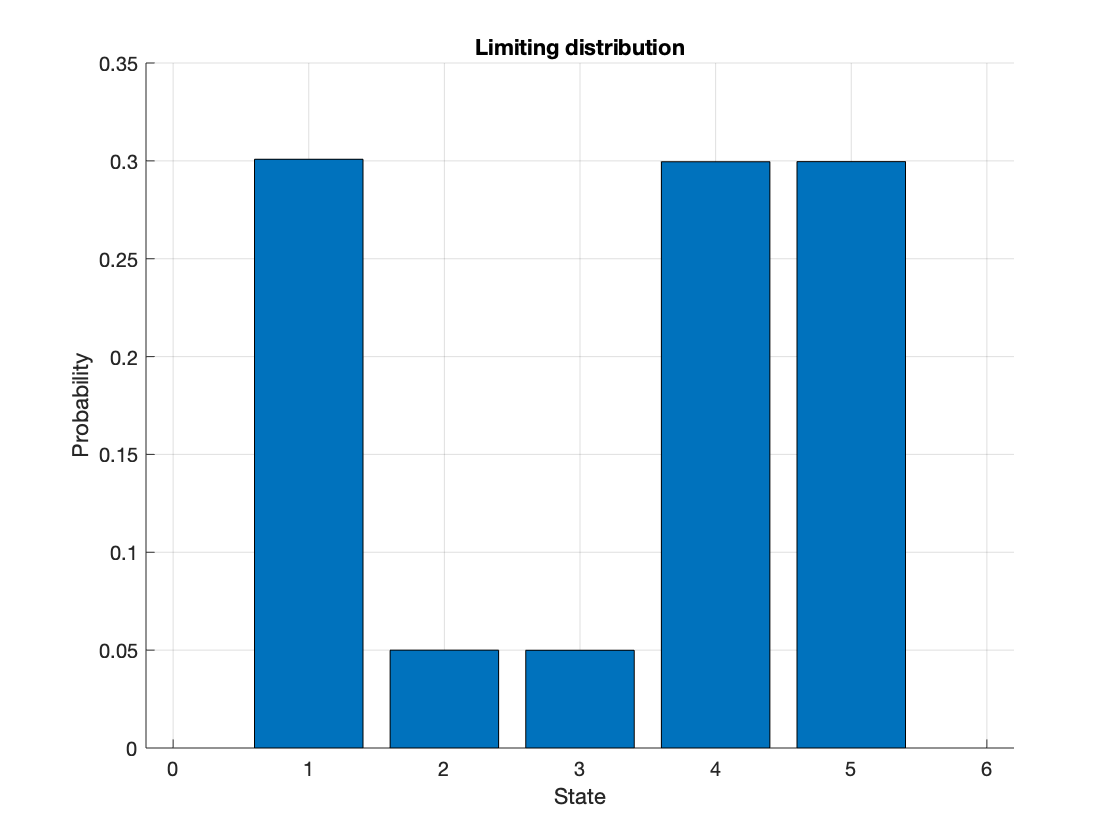

P_est = mean(P, 3);
[V, D, W] = eig(P_est);

stationar_distr_eig = W(:,1) / sum(W(:,1));

figure
title('Limiting distribution')
xlabel('State')
ylabel('Probability')   
hold on
grid on
bar(stationar_distr_eig)
hold off

Compute mixing time

eig_values = diag(D);
alpha_star = max(abs(eig_values(2:N_states)));
spectral_gap = 1 - alpha_star;

mixing_time = - log(2 * eps * min(stationar_distr_eig)) / spectral_gap;
mixing_time

mixing_time = 92.7104